dataFolder = '/GEE_30m';
labelIDs = [0 1];
pixelLabelIDs = {0 1};
classes = ["no_label", "flood"];

imgDir = fullfile(pwd, dataFolder, '/train', 'images');
imds = imageDatastore(imgDir, 'readfcn',@(filename) custominputreader(imread(filename)));

floodLabelSmoothThreshold = 0.3;
sigma = 2;
labelDir = fullfile(pwd, dataFolder, '/train', 'labels');
filllabeler =  @(image) customlabelreader(image, floodLabelSmoothThreshold, sigma);
pxds = pixelLabelDatastore(labelDir, classes, pixelLabelIDs,'readfcn',@(filename) filllabeler(imread(filename)));
a = combine(imds, pxds)

a =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 matlab.io.datastore.PixelLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]


a.read()

ans = 1×2 cell array
    {1016×1234×2 uint8}    {1016×1234 categorical}


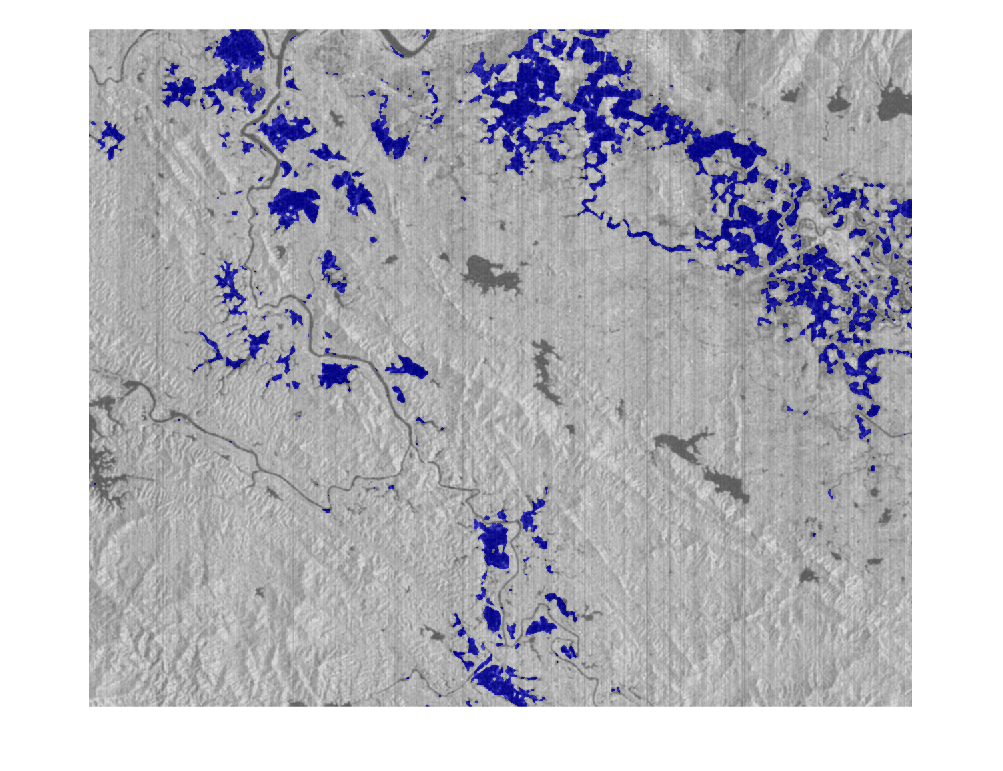

i = imds.preview;
c = pxds.preview;
i1 = normalize(double(i), 'range', [0 1]);
i1 = i1(:,:,1);
c1 = double(c);
b = labeloverlay(i1,c1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(b);

tbl = countEachLabel(pxds_pre)

tbl = 2×3 table
        Name        PixelCount    ImagePixelCount
    ____________    __________    _______________

    {'no_label'}    3.3904e+07      3.5297e+07   
    {'flood'   }    1.3929e+06      3.5297e+07   


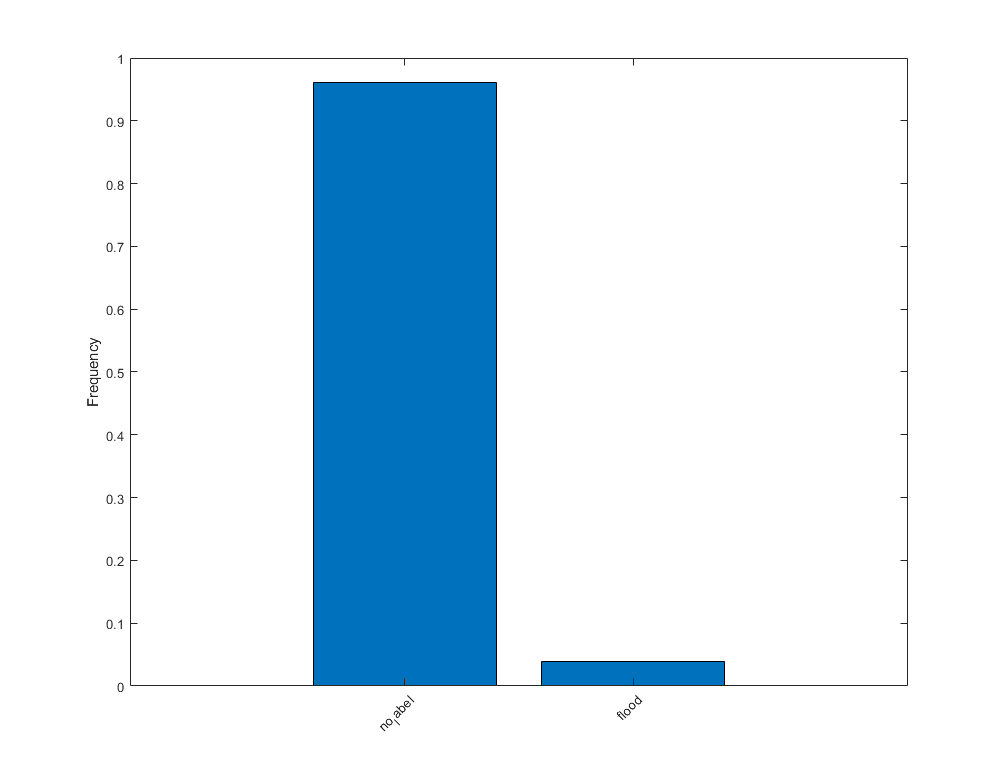

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes))
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

% imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
% classWeights = median(imageFreq) ./ imageFreq

inputTileSize = [128, 128, 2];
patchesPerImage = 50;
biasThreshold = 0.5;
timeToLoop = 10000;

augmenter = imageDataAugmenter("RandRotation",[-90, 90], ...
    "RandYTranslation", [-10 10], ...
    'RandXTranslation', [-10 10], ...
    "RandXReflection", true);
dsTrain = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), biasThreshold, timeToLoop, "PatchesPerImage", patchesPerImage, 'DataAugmentation', augmenter);
inputBatch = preview(dsTrain);
disp(inputBatch)

       InputImage        ResponsePixelLabelImage
    _________________    _______________________

    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 



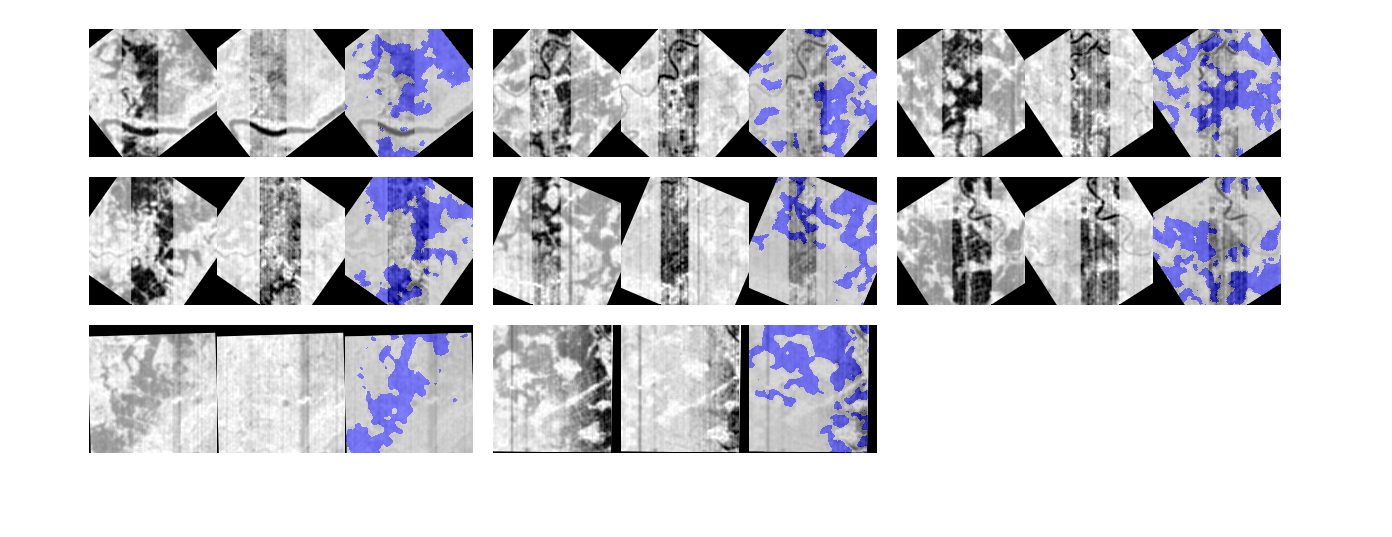

showImageWithLabel(inputBatch)

valImgDir = fullfile(pwd, dataFolder, '/validate', 'images');
valImds = imageDatastore(valImgDir,'readfcn',@(filename) custominputreader(imread(filename)));
valLabelDir = fullfile(pwd, dataFolder, '/validate', 'labels');
valPxds = pixelLabelDatastore(valLabelDir, classes, pixelLabelIDs, 'readfcn', @(filename) filllabeler(imread(filename)));
dsValidate = imbalanceRandomPatchExtractionDatastore(valImds, valPxds, inputTileSize(1:2), biasThreshold, timeToLoop, ...
    "PatchesPerImage", patchesPerImage, ...
    'DataAugmentation', augmenter);

pxLayer = dicePixelClassificationLayer('Name','dice-Pixel-Classification-Layer','Classes',tbl.Name);
% pxLayer = pixelClassificationLayer('Name','Pixel-Classification-Layer','Classes',tbl.Name);%,'ClassWeights',classWeights);
% lgraph = createUnet(inputTileSize, numel(classes), pxLayer);
lgraph = unetLayers(inputTileSize, numel(classes), "EncoderDepth", 4);
lgraph = replaceLayer(lgraph, 'Segmentation-Layer', pxLayer);
disp(lgraph.Layers)

  58×1 Layer array with layers:

     1   'ImageInputLayer'                      Image Input                       128×128×2 images with 'zerocenter' normalization
     2   'Encoder-Stage-1-Conv-1'               Convolution                       64 3×3 convolutions with stride [1  1] and padding 'same'
     3   'Encoder-Stage-1-ReLU-1'               ReLU                              ReLU
     4   'Encoder-Stage-1-Conv-2'               Convolution                       64 3×3 convolutions with stride [1  1] and padding 'same'
     5   'Encoder-Stage-1-ReLU-2'               ReLU                              ReLU
     6   'Encoder-Stage-1-MaxPool'              Max Pooling                       2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'Encoder-Stage-2-Conv-1'               Convolution                       128 3×3 convolutions with stride [1  1] and padding 'same'
     8   'Encoder-Stag

initialLearningRate = 0.05;
maxEpochs = 100;
minibatchSize = 8;
l2reg = 0.0001;

options = trainingOptions('sgdm',...
    'InitialLearnRate',initialLearningRate,...
    'Momentum',0.9,...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs,...
    'MiniBatchSize',minibatchSize,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor', 0.1,...
    'LearnRateDropPeriod', 5,...
    'Shuffle','every-epoch',...
    'GradientThresholdMethod','l2norm',...
    'Plots','training-progress',...
    'VerboseFrequency',20,...
    "ExecutionEnvironment","gpu");
%     'ValidationData', dsValidate,...
%     'ValidationFrequency', 500,...
%     'GradientThreshold',6,...
%     "CheckpointPath", strcat(pwd, dataFolder, '/checkpoint'));

doTraining = true;
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    [net,info] = trainNetwork(dsTrain,lgraph,options);
    %     save(['savedUnet-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net','options');
end

Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:05 |       65.98% |       0.5840 |          0.0500 |


|       1 |          20 |       00:02:24 |       69.13% |       0.5913 |          0.0500 |


|       1 |          40 |       00:02:42 |       65.69% |       0.5821 |          0.0500 |


|       1 |          60 |       00:02:57 |       55.31% |       0.5527 |          0.0500 |


|       1 |          80 |       00:03:17 |       56.64% |       0.5734 |          0.0500 |


|       2 |         100 |       00:05:48 |       65.08% |       0.4700 |          0.0500 |


|       2 |         120 |       00:07:45 |       68.32% |       0.5898 |          0.0500 |


|       2 |         140 |       00:08:04 |       58.05% |       0.5809 |          0.0500 |


|       2 |         160 |       00:08:15 |       60.13% |       0.5764 |          0.0500 |


|       2 |         180 |       00:08:37 |       65.12% |       0.5780 |          0.0500 |


|       3 |         200 |       00:08:51 |       65.36% |       0.5701 |          0.0500 |


|       3 |         220 |       00:12:03 |       99.96% |       0.2909 |          0.0500 |


|       3 |         240 |       00:13:29 |       69.10% |       0.5988 |          0.0500 |


|       3 |         260 |       00:13:46 |       58.98% |       0.5607 |          0.0500 |


|       4 |         280 |       00:13:57 |       64.55% |       0.5737 |          0.0500 |


|       4 |         300 |       00:14:16 |       55.89% |       0.5746 |          0.0500 |


|       4 |         320 |       00:14:36 |       53.11% |       0.5815 |          0.0500 |


|       4 |         340 |       00:15:00 |       69.84% |       0.5983 |          0.0500 |


|       4 |         360 |       00:15:18 |       66.50% |       0.5747 |          0.0500 |


|       5 |         380 |       00:15:47 |       53.93% |       0.5739 |          0.0500 |


|       5 |         400 |       00:16:01 |       69.09% |       0.5941 |          0.0500 |


|       5 |         420 |       00:18:37 |       67.93% |       0.5868 |          0.0500 |


|       5 |         440 |       00:18:56 |       65.89% |       0.5896 |          0.0500 |


|       5 |         460 |       00:19:21 |       62.27% |       0.5704 |          0.0500 |


|       6 |         480 |       00:19:49 |       66.51% |       0.5857 |          0.0050 |


|       6 |         500 |       00:20:08 |       54.77% |       0.5753 |          0.0050 |


|       6 |         520 |       00:20:21 |       61.05% |       0.5777 |          0.0050 |


|       6 |         540 |       00:23:15 |      100.00% |       0.0637 |          0.0050 |


|       7 |         560 |       00:23:35 |       68.21% |       0.5895 |          0.0050 |


|       7 |         580 |       00:23:52 |       59.26% |       0.5485 |          0.0050 |


|       7 |         600 |       00:24:08 |       65.89% |       0.5759 |          0.0050 |


|       7 |         620 |       00:24:25 |       67.45% |       0.5834 |          0.0050 |


|       7 |         640 |       00:24:49 |       66.88% |       0.5970 |          0.0050 |


|       8 |         660 |       00:25:05 |       59.60% |       0.5486 |          0.0050 |


|       8 |         680 |       00:27:54 |       64.04% |       0.5740 |          0.0050 |


|       8 |         700 |       00:28:14 |       64.64% |       0.5690 |          0.0050 |


|       8 |         720 |       00:28:28 |       53.35% |       0.5845 |          0.0050 |


|       8 |         740 |       00:28:49 |       56.98% |       0.5662 |          0.0050 |


|       9 |         760 |       00:29:06 |       69.15% |       0.5944 |          0.0050 |


|       9 |         780 |       00:29:28 |       66.85% |       0.5829 |          0.0050 |


|       9 |         800 |       00:29:46 |       49.73% |       0.5655 |          0.0050 |


|       9 |         820 |       00:30:02 |       69.09% |       0.5975 |          0.0050 |


|      10 |         840 |       00:30:21 |       64.58% |       0.5722 |          0.0050 |


|      10 |         860 |       00:32:49 |       57.76% |       0.5525 |          0.0050 |


|      10 |         880 |       00:33:07 |       57.83% |       0.5682 |          0.0050 |


|      10 |         900 |       00:33:25 |       63.16% |       0.6005 |          0.0050 |


|      10 |         920 |       00:33:48 |       64.17% |       0.5755 |          0.0050 |


|      11 |         940 |       00:34:02 |       57.68% |       0.5991 |          0.0005 |


|      11 |         960 |       00:34:23 |       58.87% |       0.5611 |          0.0005 |


|      11 |         980 |       00:36:51 |       58.11% |       0.5794 |          0.0005 |


|      11 |        1000 |       00:37:01 |       65.20% |       0.5792 |          0.0005 |


|      11 |        1020 |       00:37:15 |       55.45% |       0.6143 |          0.0005 |


|      12 |        1040 |       00:37:31 |       63.76% |       0.5699 |          0.0005 |


|      12 |        1060 |       00:37:48 |       64.15% |       0.5720 |          0.0005 |


|      12 |        1080 |       00:38:11 |       60.34% |       0.5704 |          0.0005 |


|      12 |        1100 |       00:38:27 |       70.29% |       0.6017 |          0.0005 |


|      13 |        1120 |       00:40:21 |       99.93% |       0.1963 |          0.0005 |


|      13 |        1121 |       00:40:35 |       99.99% |       0.1915 |          0.0005 |
|========================================================================================|


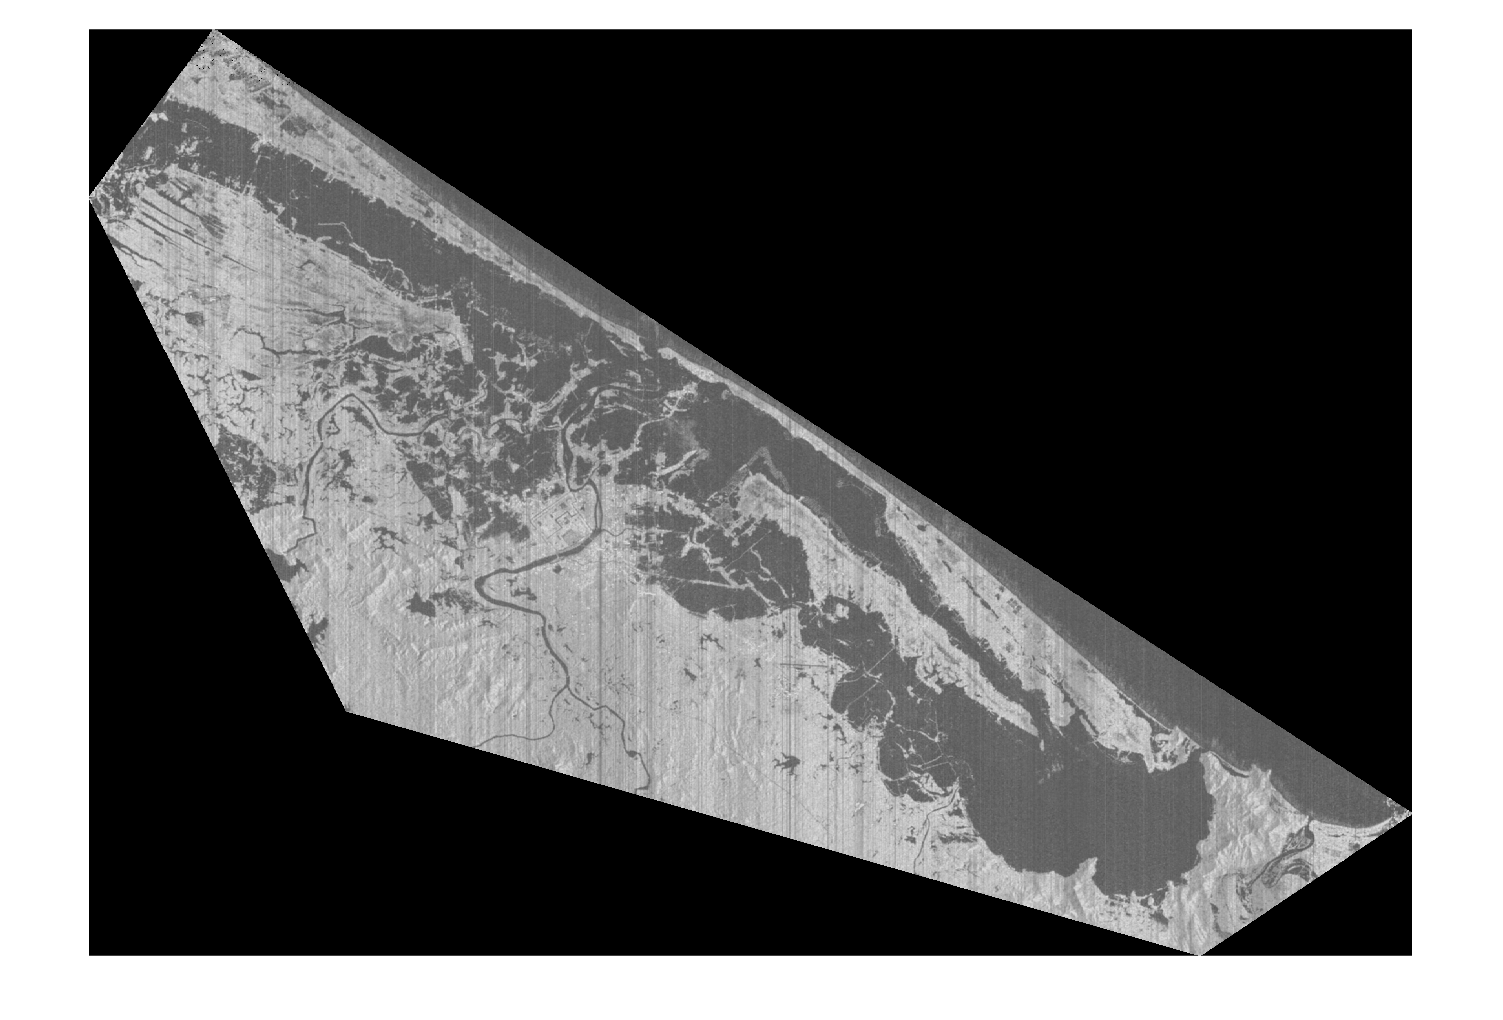

predictPatchSize = [1024 1024];
test_data = imread('C:\Do-an\GEE_30m\test\images\input_hue_1010.tif');
i2 = custominputreader(test_data);
% imshow(i2);
segmentedImage = segmentImage(i2,net,predictPatchSize);
t1 = normalize(test_data(:,:,1), 'range', [0 1]);
s1 = double(segmentedImage);
b = labeloverlay(t1,s1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(b);

unique(segmentedImage)

ans = uint8
1